# NR FDD Scheduling Performance Evaluation

This example models scheduling of downlink (DL) and uplink (UL) resources and measures network performance in frequency division duplexing (FDD) mode. The example includes three different scheduling strategies and you can also integrate your custom scheduling strategy. To evaluate the network performance with different data traffic patterns, the example also models the radio link control layer in unacknowledged mode (RLC-UM) with logical channel prioritization (LCP) procedure. To model PHY, a probability-based passthrough physical (PHY) layer without any signal processing is used. You can switch to the 5G Toolbox™ PHY layer for high fidelity modeling. The performance of the scheduling strategy is evaluated in terms of the achieved throughput and fairness in resource sharing.

## Introduction

This example shows how a scheduling strategy (controlled by the gNB) assigns UL and DL resources among the UEs. The example considers the following operations within the gNB and UEs that facilitate UL and DL transmissions and receptions.

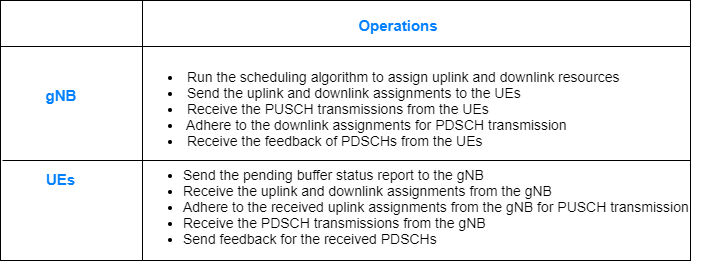

The complete PUSCH or PDSCH packet is transmitted in the first symbol of its allocated symbol set. Receiver processes the packet in the symbol just after the last symbol in the allocated symbol set.

The schedulers (UL and DL) run every *p* slots to assign the UL and DL resources, where *p* is the configured periodicity of the scheduler. In each run, the number of slots scheduled is equal to the periodicity of scheduler run, *p*.

**UL Scheduler**

The first slot, among the *p* slots to be scheduled in a run, is the nearest upcoming slot which satisfies the PUSCH preparation time capability of UEs. For example, the figure shows the way scheduler selects the slots during two consecutive runs. It assumes scheduler periodicity (*p)* of 3 slots. Hence, the scheduler runs after every 3 slots, and schedules resources for 3 slots. PUSCH preparation time capability for all the UEs is assumed as greater than 1 slot (14 symbols) but less than 2 slots (28 symbols).

- Run-1: When scheduler runs at the start of Slot-A, it schedules 3 slots starting from Slot-C, because for Slot-A and Slot-B the UEs do not get enough PUSCH preparation time (UEs gets a time of 0 symbols at start of Slot-A and 14 symbols at start of Slot-B). For Slot-C, UEs get 28 symbols for PUSCH preparation and this satisfies the PUSCH preparation time capability. Hence, Slot-C, D, and E are scheduled in this run.

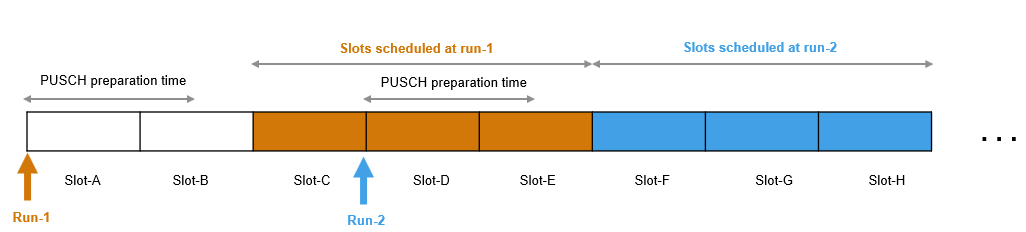

- Run-2: When scheduler runs at the start of Slot-D, it schedules the next 3 contiguous slots starting from Slot-F (Slot-F, G, and H).

**DL Scheduler**

The first slot, among the *p* slots to be scheduled in a run, is the immediate next slot.

- Run-1: When scheduler runs at the start of Slot-A, it schedules 3 contiguous slots Slot-B, C, and D.

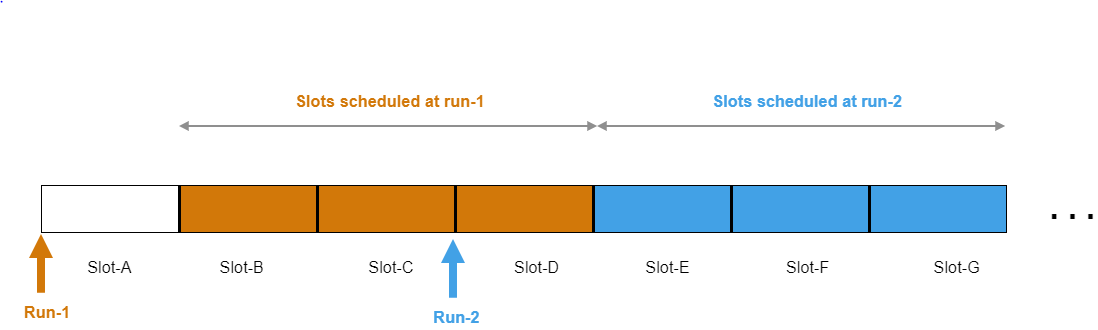

- Run-2: When scheduler runs at the start of Slot-D, it schedules 3 contiguous slots Slot-E, F, and G.

You can choose any one of the implemented scheduling strategies: proportional fair (PF), best CQI, or round robin (RR). The various supported inputs to the UL scheduler are listed along with the scheduling strategies that consider them.

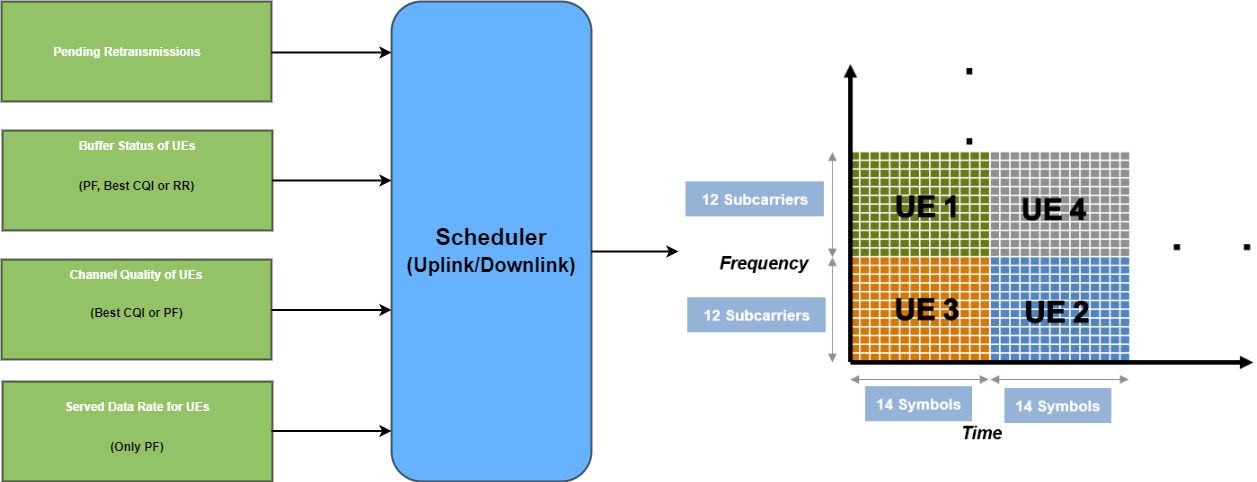

The control packets required are assumed to be sent out of band without the need of resources for transmission. The control packets are UL assignment, DL assignment, buffer status report (BSR), and PDSCH feedback.

The demodulation reference signal (DM-RS) is not modeled in this example. However, one symbol is kept unused for it in the PUSCH and PDSCH assignments.

This example models:

- Slot-based and symbol-based DL and UL scheduling.

- Noncontiguous allocation of frequency-domain resources in terms of resource block groups (RBGs).

- Configurable subcarrier spacing resulting in different slot durations.

- Asynchronous adaptive hybrid automatic repeat request (HARQ) mechanism in UL and DL.

- Multiple logical channels (LCHs) to support different kind of applications.

- Logical channel prioritization (LCP) to distribute the received assignment among logical channels per UE for UL and DL.

## Scenario Configuration

Configure simulation parameters in the `simParameters` structure.

rng('default'); % Reset the random number generator
simParameters = []; % Clear the simulation parameters
simParameters.NumFramesSim = 100; % Simulation time in terms of number of 10 ms frames

Specify the number of UEs in the cell, assuming that UEs have sequential radio network temporary identifiers (RNTIs) from `1` to `simParameters.NumUEs`. If you change the number of UEs, ensure that the number of rows in `simParameters.UEPosition` parameter equals to the value of `simParameters.NumUEs`.

simParameters.NumUEs = 4;
% Assign position to the UEs assuming that the gNB is at (0, 0, 0). N-by-3
% matrix where 'N' is the number of UEs. Each row has (x, y, z) position of
% a UE (in meters)
simParameters.UEPosition = [100 0 0;
                            250 0 0;
                            700 0 0;
                            750 0 0];
% Validate the UE positions
validateattributes(simParameters.UEPosition, {'numeric'}, {'nonempty', 'real', 'nrows', simParameters.NumUEs, 'ncols', 3, 'finite'}, 'simParameters.UEPosition', 'UEPosition');

Set the channel bandwidth to 30 MHz and subcarrier spacing (SCS) to 15 kHz as defined in 3GPP TS 38.104 Section 5.3.2. The complete bandwidth is assumed to be allotted for PUSCH/PDSCH.

simParameters.DLBandwidth = 30e6; % Hz
simParameters.ULBandwidth = 30e6; % Hz
simParameters.NumRBs = 160;
simParameters.SCS = 15; % kHz
simParameters.DLCarrierFreq = 2.635e9; % Hz
simParameters.ULCarrierFreq = 2.515e9; % Hz

Configure parameters to update UL channel quality at gNB and DL channel quality at gNB and UE. Channel conditions are periodically improved or deteriorated by CQIDelta every channelUpdatePeriodicity seconds for all RBs of a UE. Whether channel conditions for a particular UE improve or deteriorate is randomly determined.

`RBCQI = RBCQI +/- CQIDelta`

simParameters.ChannelUpdatePeriodicity = 0.2; % In sec
simParameters.CQIDelta = 2;

Configure a mapping between distance from gNB (first column in meters) and maximum achievable UL CQI value (second column). For example, if a UE is 700 meters away from the gNB, it can achieve a maximum CQI value of 10 as the distance falls within the [501, 800] meters range, as per the mapping. Set the distance in increasing order and the maximum achievable CQI value in decreasing order. This mapping is only applicable when passthrough PHY is used.

simParameters.CQIvsDistance = [
    200  15;
    500  12;
    800  10;
    1000  8;
    1200  7];

Specify BSR periodicity and HARQ entity configuration.

simParameters.BSRPeriodicity = 5; % In ms
simParameters.EnableHARQ = true; % Flag to enable or disable HARQ. If disabled, there are no retransmissions
simParameters.NumHARQ = 16; % Number of HARQ processes

Configure scheduler run periodicity (in terms of number of slots), scheduler type (slot-based or symbol-based), and scheduler strategy used for allocating the PUSCH/PDSCH resources. When proportional fair scheduling is configured, specify the moving average parameter within the range [0, 1] to calculate average data rate for a UE in UL and DL directions. Parameter value closer to 1 implies more weight on the instantaneous data rate. Parameter value closer to 0 implies more weight on the past data rate.

`AverageDataRate = ((1 - MovingAvgDataRateWeight) * PastDataRate) + (MovingAvgDataRateWeight * InstantaneousDataRate)`

simParameters.SchedulerPeriodicity = 4; % Value must be less than the number of slots in a 10 ms frame
simParameters.SchedulingType = 0; % Set the value to 0 (slot-based scheduling) or 1 (symbol-based scheduling)
simParameters.SchedulerStrategy = 'PF'; % Supported scheduling strategies: 'PF', 'RR' and 'BestCQI'
simParameters.MovingAvgDataRateWeight = 0.5;

Specify the PUSCH preparation parameter. gNB ensures that PUSCH assignment is received at the UEs at least `PUSCHPrepTime` ahead of the transmission time.

simParameters.PUSCHPrepTime = 200; % In microseconds 

Specify the maximum limit on the RBs allotted for PDSCH and PUSCH. The transmission limit applies only to new transmissions and not to the retransmissions.

simParameters.RBAllocationLimitUL = 100; % For PUSCH
simParameters.RBAllocationLimitDL = 100; % For PDSCH

### Logical Channel Configuration

Load the logical channel configuration table. Each row in the table represents one logical channel and has these properties as columns.

- RNTI - Radio network temporary identifier of the UE.

- LogicalChannelID - Logical channel identifier.

- LCGID - Logical channel group identifier.

- SeqNumFieldLength - Defines the sequence number field length. It takes either 6 or 12.

- MaxTxBufferSDUs - Maximum Tx buffer size in terms of number of higher layer service data units (SDUs).

- ReassemblyTimer - Defines the reassembly timer (in ms).

- EntityType - Defines the RLC entity type. It takes values 0, 1, and 2, which indicates whether the RLC UM entity is unidirectional DL, unidirectional UL, or bidirectional UM, respectively.

- Priority - Priority of the logical channel.

- PBR - Prioritized bit rate (in kilo bytes per second).

- BSD - Bucket size duration (in ms).

load('NRFDDRLCChannelConfig.mat')
simParameters.RLCChannelConfig = RLCChannelConfig;

### Application Traffic Configuration

Load the application configuration table containing these fields. Each row in the table represents one application and has these properties as columns.

- DataRate - Application traffic generation rate (in kilo bits per second).

- PacketSize - Size of the packet (in bytes).

- HostDevice - Defines the device (UE or gNB) on which the application is installed with the specified configuration. The device takes values 0 or 1. The values indicate the application is configured on gNB side or UE side, respectively.

- RNTI - Radio network temporary identifier of a UE. This identifies the UE for which the application is installed.

- LCID - Logical channel identifier.

load('NRFDDAppConfig.mat');
% Validate the host device type for the applications configured
validateattributes(AppConfig.HostDevice, {'numeric'}, {'nonempty', 'integer', '>=', 0, '<=', 1}, 'AppConfig.HostDevice', 'HostDevice');

### Logging and visualization configuration

The `CQIVisualization` and `RBVisualization` parameters control the display of the CQI visualization and the RB assignment visualization respectively. By default, these plots are disabled. You can enable them by setting the respective flags to true.

simParameters.CQIVisualization = false;
simParameters.RBVisualization = false;

Set the `enableTraces` as `true` to log the traces. If the `enableTraces` is set to `false`, then `CQIVisualization` and `RBVisualization` are disabled automatically and traces are not logged in the simulation. To speed up the simulation, set the `enableTraces` to `false`.

enableTraces = true;

The example updates the metrics plots periodically. Set the number of updates during the simulation.

simParameters.NumMetricsSteps = 20;

Write the logs to MAT-files. The example uses these logs for post-simulation analysis and visualization.

parametersLogFile = 'simParameters'; % For logging the simulation parameters
simulationLogFile = 'simulationLogs'; % For logging the simulation traces
simulationMetricsFile = 'simulationMetrics'; % For logging the simulation metrics

## Derived Parameters

Based on the primary configuration parameters, compute the derived parameters. Additionally, set some example specific constants.

simParameters.DuplexMode = 0; % FDD
% Size of sub-band for CQI reporting in terms of number of RBs (Only used
% when 5G Toolbox™ PHY layer processing is enabled)
simParameters.SubbandSize = 16;
simParameters.NumCells = 1; % Number of cells
simParameters.NCellID = 1; % Physical cell ID
simParameters.GNBPosition = [0 0 0]; % Position of gNB in (x,y,z) coordinates

Compute the number of slots and symbols in the simulation.

numSlotsSim = (simParameters.NumFramesSim * 10 * simParameters.SCS)/15; % Number of slots in the simulation
numSymbolsSim = numSlotsSim * 14; % Number of symbols in the simulation (assuming normal cyclic prefix)

Calculate maximum achievable CQI value for the UEs based on their distance from the gNB.

maxUECQIs = zeros(simParameters.NumUEs, 1); % To store the maximum achievable CQI value for UEs
for ueIdx = 1:simParameters.NumUEs
    ueDistance = norm(simParameters.UEPosition(ueIdx, :) - simParameters.GNBPosition);
    % Based on the distance of the UE from gNB, find matching row in
    % CQIvsDistance mapping
    matchingRowIdx = find(simParameters.CQIvsDistance(:, 1) > ueDistance);
    if isempty(matchingRowIdx)
        maxUECQIs(ueIdx) = simParameters.CQIvsDistance(end, 2);
    else
        maxUECQIs(ueIdx) = simParameters.CQIvsDistance(matchingRowIdx(1), 2);
    end
end

Define initial UL and DL channel quality as an N-by-P matrix, where 'N' is the number of UEs and 'P' is the number of RBs in the carrier bandwidth.

simParameters.InitialChannelQualityDL = zeros(simParameters.NumUEs, simParameters.NumRBs); % To store current DL CQI values on the RBs for different UEs
for ueIdx = 1:simParameters.NumUEs
    % Assign random CQI values for the RBs, limited by the maximum achievable CQI value
    simParameters.InitialChannelQualityDL(ueIdx, :) = randi([1 maxUECQIs(ueIdx)], 1, simParameters.NumRBs);
end
% Initially, DL and UL CQI values are assumed to be equal
simParameters.InitialChannelQualityUL = simParameters.InitialChannelQualityDL;

Get the logical channel information associated per UE. This information helps in RLC metrics logging and visualization.

lchInfo = repmat(struct('RNTI', [], 'LCID', [], 'EntityDir', []), [simParameters.NumUEs 1]);
for ueIdx = 1:simParameters.NumUEs
    lchInfo(ueIdx).RNTI = ueIdx;
    lchInfo(ueIdx).LCID = simParameters.RLCChannelConfig.LogicalChannelID(simParameters.RLCChannelConfig.RNTI == ueIdx);
    lchInfo(ueIdx).EntityDir = simParameters.RLCChannelConfig.EntityType(simParameters.RLCChannelConfig.RNTI == ueIdx);
end

Set the simulation tick granularity (in terms of OFDM symbols) and the mapping type as per the configured scheduling type.

if ~isfield(simParameters, 'SchedulingType') || simParameters.SchedulingType == 0 % If no scheduling type is specified or slot-based scheduling is specified
    tickGranularity = 14;
    simParameters.PUSCHMappingType = 'A';
    simParameters.PDSCHMappingType = 'A';
else % Symbol-based scheduling
    tickGranularity = 1;
    simParameters.PUSCHMappingType = 'B';
    simParameters.PDSCHMappingType = 'B';
end

Set the interval at which the example updates metrics visualization in terms of number of slots. Because this example uses a time granularity of one slot, the `MetricsStepSize` field must be an integer.

simParameters.MetricsStepSize = ceil(numSlotsSim / simParameters.NumMetricsSteps);
if mod(numSlotsSim, simParameters.NumMetricsSteps) ~= 0
    % Update the NumMetricsSteps parameter if NumSlotsSim is not
    % completely divisible by it
    simParameters.NumMetricsSteps = floor(numSlotsSim / simParameters.MetricsStepSize);
end

## gNB and UEs Setup

Create the gNB and UE objects, initialize the channel quality information for UEs, and set up the logical channel at gNB and UE. The helper classes [hNRGNB.m](matlab:edit('hNRGNB')) and [hNRUE.m](matlab:edit('hNRUE')) create gNB and UE nodes respectively, containing the RLC and medium access control (MAC) layers. For MAC layer, [hNRGNB.m](matlab:edit('hNRGNB')) uses the helper class [hNRGNBMAC.m](matlab:edit('hNRGNBMAC')) to implement the gNB MAC functionality and  [hNRUE.m](matlab:edit('hNRUE')) uses [hNRUEMAC.m](matlab:edit('hNRUEMAC')) to implement the UE MAC functionality. Schedulers are implemented in [hNRSchedulerRoundRobin.m](matlab:edit('hNRSchedulerRoundRobin')) (RR), [hNRSchedulerProportionalFair.m](matlab:edit('hNRSchedulerProportionalFair')) (PF), [hNRSchedulerBestCQI.m](matlab:edit('hNRSchedulerBestCQI')) (Best CQI). All the schedulers inherit from the base class [hNRScheduler.m](matlab:edit('hNRScheduler')) which contains the core scheduling functionality. For RLC layer, both [hNRGNB.m](matlab:edit('hNRGNB')) and [hNRUE.m](matlab:edit('hNRUE')) use [hNRUMEntity.m](matlab:edit('hNRUMEntity')) to implement the functionality of the RLC transmitter and receiver. Passthrough PHY layer for UE and gNB is implemented in [hNRUEPassThroughPhy.m](matlab:edit('hNRUEPassThroughPhy')) and [hNRGNBPassThroughPhy.m](matlab:edit('hNRGNBPassThroughPhy')), respectively.

simParameters.Position = simParameters.GNBPosition;
gNB = hNRGNB(simParameters); % Create gNB node

% Create and add scheduler
switch(simParameters.SchedulerStrategy)
    case 'RR' % Round robin scheduler
        scheduler = hNRSchedulerRoundRobin(simParameters);
    case 'PF' % Proportional fair scheduler
        scheduler = hNRSchedulerProportionalFair(simParameters);
    case 'BestCQI' % Best CQI scheduler
        scheduler = hNRSchedulerBestCQI(simParameters);
end
addScheduler(gNB, scheduler); % Add scheduler to gNB

gNB.PhyEntity = hNRGNBPassThroughPhy(simParameters); % Add passthrough PHY
configurePhy(gNB, simParameters);
setPhyInterface(gNB); % Set the interface to PHY layer

% Create the set of UE nodes
UEs = cell(simParameters.NumUEs, 1); 
for ueIdx=1:simParameters.NumUEs
    simParameters.Position = simParameters.UEPosition(ueIdx, :); % Position of UE
    UEs{ueIdx} = hNRUE(simParameters, ueIdx);
    UEs{ueIdx}.PhyEntity = hNRUEPassThroughPhy(simParameters, ueIdx); % Add passthrough PHY
    configurePhy(UEs{ueIdx}, simParameters);
    setPhyInterface(UEs{ueIdx}); % Set the interface to PHY layer
    
    % Initialize the UL CQI values at gNB scheduler
    channelQualityInfoUL = struct('RNTI', ueIdx, 'CQI', simParameters.InitialChannelQualityUL(ueIdx, :));
    updateChannelQualityUL(gNB.MACEntity.Scheduler, channelQualityInfoUL);
    
    % Initialize the DL CQI values at gNB scheduler
    channelQualityInfoDL = struct('RNTI', ueIdx, 'CQI', simParameters.InitialChannelQualityDL(ueIdx, :));
    updateChannelQualityDL(gNB.MACEntity.Scheduler, channelQualityInfoDL);
 
    % Initialize the DL CQI values at UE for packet error probability estimation
    updateChannelQualityDL(UEs{ueIdx}.MACEntity, channelQualityInfoDL);
end

% Setup logical channels
for lchInfoIdx = 1:size(simParameters.RLCChannelConfig, 1)
    rlcChannelConfigStruct = table2struct(simParameters.RLCChannelConfig(lchInfoIdx, :));
    ueIdx = simParameters.RLCChannelConfig.RNTI(lchInfoIdx);
    % Setup the logical channel at gNB and UE
    gNB.configureLogicalChannel(ueIdx, rlcChannelConfigStruct);
    UEs{ueIdx}.configureLogicalChannel(ueIdx, rlcChannelConfigStruct);
end

% Add data traffic pattern generators to gNB and UE nodes
for appIdx = 1:size(AppConfig, 1)
    
    % Create an object for On-Off network traffic pattern
    app = networkTrafficOnOff('PacketSize', AppConfig.PacketSize(appIdx), 'GeneratePacket', true, ...
            'OnTime', simParameters.NumFramesSim/100, 'OffTime', 0, 'DataRate', AppConfig.DataRate(appIdx));

    if AppConfig.HostDevice(appIdx) == 0
        % Add traffic pattern that generates traffic on downlink
        addApplication(gNB, AppConfig.RNTI(appIdx), AppConfig.LCID(appIdx), app);
    else
        % Add traffic pattern that generates traffic on uplink
        addApplication(UEs{AppConfig.RNTI(appIdx)}, AppConfig.RNTI(appIdx), AppConfig.LCID(appIdx), app);
    end
end

% Setup the UL and DL packet distribution mechanism
simParameters.MaxReceivers = simParameters.NumUEs + 1; % Number of nodes
% Create packet distribution object
packetDistributionObj = hNRPacketDistribution(simParameters);
hNRSetUpPacketDistribution(simParameters, gNB, UEs, packetDistributionObj);

## Processing Loop

Simulation is run slot by slot. In each slot, these operations are executed:

- Run the MAC and PHY layers of gNB

- Run the MAC and PHY layers of UEs

- Layer specific logging and visualization

- Advance the timer for the nodes. Every 1 ms it also sends trigger to application and RLC layers. Application layer and RLC layer execute their scheduled operations based on 1 ms timer trigger.

Create objects to log and visualize RLC and MAC traces

if enableTraces
    % Create an object for RLC traces logging
    simRLCLogger = hNRRLCLogger(simParameters, lchInfo);
    % Create an object for MAC traces logging
    simSchedulingLogger = hNRSchedulingLogger(simParameters);
    % Create an object for CQI and RB grid visualization
    if simParameters.CQIVisualization || simParameters.RBVisualization
        gridVisualizer = hNRGridVisualizer(simParameters, 'MACLogger', simSchedulingLogger);
    end
end

Create an object for RLC and MAC metrics visualization.

nodes = struct('UEs', {UEs}, 'GNB', gNB);
metricsVisualizer = hNRMetricsVisualizer(simParameters, 'Nodes', nodes, 'EnableSchedulerMetricsPlots', true, 'EnableRLCMetricsPlots', true, 'LCHInfo', lchInfo);

Run the processing loop.

slotNum = 0;

% Execute all the symbols in the simulation
for symbolNum = 1 : tickGranularity : numSymbolsSim
    if mod(symbolNum - 1, 14) == 0
        slotNum = slotNum + 1;
    end
    
    % Run MAC and PHY of gNB
    run(gNB);
    
    % Run MAC and PHY of UEs
    for ueIdx = 1:simParameters.NumUEs
        run(UEs{ueIdx});
    end

    if enableTraces
        % RLC logging (only at slot boundary)
        if (simParameters.SchedulingType == 1 && mod(symbolNum, 14) == 0) || (simParameters.SchedulingType == 0 && mod(symbolNum-1, 14) == 0)
            logCellRLCStats(simRLCLogger, gNB, UEs);
        end

        % MAC logging
        logCellSchedulingStats(simSchedulingLogger, symbolNum, gNB, UEs);
    end
    
    % Visualization    
    % Check slot boundary
    if symbolNum > 1 && ((simParameters.SchedulingType == 1 && mod(symbolNum, 14) == 0) || (simParameters.SchedulingType == 0 && mod(symbolNum-1, 14) == 0))
        % If the update periodicity is reached, plot RLC metrics and scheduler metrics at slot boundary
        if mod(slotNum, simParameters.MetricsStepSize) == 0
            plotLiveMetrics(metricsVisualizer);
        end
    end
    
    % Advance timer ticks for gNB and UEs by 14 symbols
    advanceTimer(gNB, tickGranularity);
    for ueIdx = 1:simParameters.NumUEs
        advanceTimer(UEs{ueIdx}, tickGranularity);
    end
end

Get the simulation metrics and save it in a MAT-file. The simulation metrics are saved in a MAT-file with the file name as `simulationMetricsFile`.

metrics = getMetrics(metricsVisualizer);
save(simulationMetricsFile, 'metrics');

## Simulation Visualization

The five types of run-time visualization shown are:

- *Display of CQI values for UEs over the PUSCH and PDSCH bandwidth*: You can enable this visualization in the 'Logging and Visualization Configuration' section. For details, see the 'Channel Quality Visualization' figure description in [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3) example.

- *Display of resource grid assignment to UEs*: The 2D time-frequency grid shows the resource allocation to the UEs. You can enable this visualization in the 'Logging and Visualization Configuration' section. For details, see the 'Resource Grid Allocation' figure in [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3) example.

- *Display of UL scheduling metrics plots*: The four plots displayed in 'Uplink Scheduler Performance Metrics' figure represent: UL throughput (per UE and cell), UL goodput (per UE and cell), resource share percentage among UEs (out of the total UL resources) to convey the fairness of scheduling, and pending UL buffer-status of UEs to show whether UEs are getting sufficient resources. The maximum achievable data rate value for UL throughput is shown with a dashed line in throughput and goodput plots. The performance metrics plots update for every `metricsStepSize` slots.

- *Display of DL scheduling metrics plots*: Like UL metrics plots, 'Downlink Scheduler Performance Metrics' displays corresponding subplots for DL direction. The performance metrics plots update for every `metricsStepSize` slots.

- *Display of RLC metrics plots*: The 'RLC Metrics Visualization' figure shows the number of bytes transmitted by RLC layer (per logical channel) for each UE. The RLC metrics plot updates for every `metricsStepSize` slots.

## Simulation Logs

The parameters used for simulation and the simulation logs are saved in MAT-files for post simulation analysis and visualization. The simulation parameters are saved in a MAT-file with the file name as the value of configuration parameter `parametersLogFile`. The per time step logs, scheduling assignment logs, and RLC logs are saved in the MAT-file `simulationLogFile`. After the simulation, open the file to load `DLTimeStepLogs`, `ULTimeStepLogs` `SchedulingAssignmentLogs`, and `RLCLogs` in the workspace.

**Time step logs:** Both the DL and UL time step logs follow the same format. For details of log format, see the 'Simulation Logs' section of [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3).

**Scheduling assignment logs:** Information of all the scheduling assignments and the related information is logged in this file. The table shows sample log entries.

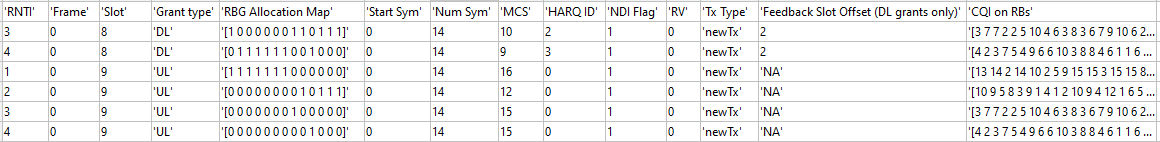

**RLC logs:** For more information on the RLC log format, see [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3).

You can run the script [NRPostSimVisualization](matlab:edit('NRPostSimVisualization.m')) to get a post simulation visualization of logs. In the post simulation script, you are provided with variable `isLogReplay`, which provides these options to visualize 'Resource Grid Allocation' and 'Channel Quality Visualization' figures.

- Set `isLogReplay` to true for replay of simulation logs.

- Set `isLogReplay` to false to analyze the details of a particular frame. In the 'Resource Grid Allocation' window, input the frame number to visualize the resource assignment for the entire frame. The frame number entered here controls the frame number for the 'Channel Quality Visualization' figure too.

if enableTraces
    % Get the logs
    simulationLogs = cell(1,1);
    logInfo = struct('DLTimeStepLogs',[], 'ULTimeStepLogs',[], 'SchedulingAssignmentLogs',[] ,'RLCLogs',[]);
    [logInfo.DLTimeStepLogs, logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger); % Scheduling assignments log
    logInfo.RLCLogs = getRLCLogs(simRLCLogger);
    simulationLogs{1} = logInfo;
    save(parametersLogFile, 'simParameters'); % Save simulation parameters in a MAT-file
    save(simulationLogFile, 'simulationLogs'); % Save simulation logs in a MAT-file
end

## Further Exploration

You can use this example to further explore these options.

### Custom scheduling

You can modify the existing scheduling strategy to implement a custom one. [Plug In Custom Scheduler in System-Level Simulation](docid:5g_ug#mw_f50a4203-9daf-4dec-88b0-6d0bc8070d5b) example explains how to create a custom scheduling strategy and plug it into system-level simulation.

### Use 5G Toolbox™ physical layer

You can also switch from passthrough PHY layer to 5G Toolbox™ physical layer processing by creating PHY objects using [hNRGNBPhy.m](matlab:edit('hNRGNBPhy.m')) and [hNRUEPhy.m](matlab:edit('hNRUEPhy.m')). For more details, see 'gNB and UEs Setup' section of [NR Cell Performance Evaluation with Physical Layer Integration](docid:5g_ug#mw_c54c277c-b9c5-4626-b12b-a5db59672570).

Based on the chosen scheduling strategy, this example shows the assignment of UL and DL resources to multiple UEs by the gNB. A run-time visualization display of the resource grid gives detailed information about the RBs allocated to each UE and the HARQ process ID assigned for transmission. UL and DL scheduling performance is analyzed based on run-time plots of throughput and goodput, resource share fairness, and pending buffer status on the UEs. A more thorough post simulation analysis by using the saved logs gives a detailed picture of the operations happening on a per slot basis.

### Use RLC AM

You can also switch the operating mode of an RLC entity from UM to acknowledged mode (AM) by modifying the input structure fields `EntityType` and `SeqNumFieldLength` in the `configureLogicalChannel` function of [hNRNode.m](matlab:edit('hNRNode.m')). Set the `EntityType` to 3 and `SeqNumFieldLength` to either 12 or 18. You can also add and set the following fields to the input structure to explore the RLC AM functionality:

- `PollRetransmitTimer`: Timer used by the transmitting side of an RLC AM entity in order to retransmit a poll

- `PollPDU`: Parameter used by the transmitting side of an RLC AM entity to trigger a poll based on number of PDUs

- `PollByte`: Parameter used by the transmitting side of an RLC AM entity to trigger a poll based on number of SDU bytes

- `MaxRetransmissions`: Maximum number of retransmissions corresponding to an RLC SDU, including its segments

- `StatusProhibitTimer`: Timer used by the receiving side of an RLC AM entity in order to prohibit frequent transmission of status PDUs

*Copyright 2019-2021 The MathWorks, Inc.*